% Input the DFT sequence
Xk = input('Input DFT sequence: ');
N = length(Xk);

xn = calcidft(Xk, N);
% Display DFT sequence
disp('DFT Sequence:');

DFT Sequence:


disp(Xk);

     1     2     3     4     5




% Display IDFT result
disp('IDFT x(n): ');

IDFT x(n): 


disp(xn);

   3.0000 + 0.0000i  -0.5000 - 0.6882i  -0.5000 - 0.1625i  -0.5000 + 0.1625i  -0.5000 + 0.6882i



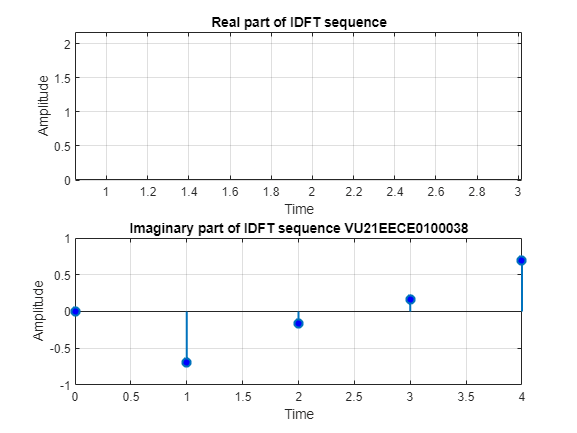


n = 0:N-1;

% Plot IDFT sequence with linewidth, color, and grid
subplot(2,1,1);
stem(n, real(xn), 'LineWidth', 1.5, 'Marker', 'o', 'MarkerFaceColor', 'r');
title('Real part of IDFT sequence');
xlabel('Time');
ylabel('Amplitude');
grid on;

subplot(2,1,2);
stem(n, imag(xn), 'LineWidth', 1.5, 'Marker', 'o', 'MarkerFaceColor', 'b');
title('Imaginary part of IDFT sequence VU21EECE0100037');
xlabel('Time');
ylabel('Amplitude');
grid

function[xn] = calcidft(Xk, N)
    xn = zeros(1, N);
    for n = 0:N-1
        for k = 0:N-1
            p = exp(1i * 2 * pi * n * k / N);
            xn(n+1) = xn(n+1) + (1/N) * Xk(k+1) * p;
        end
    end
end
